Dada la ecuación en diferencias:


$$y(n)=b_0x(n)+b_1x(n-1)+b_2x(n-2)+a_1y(n-1)+a_2y(n-2)$$


cuya función de transferencia viene dada por:


$$H(z)=\frac{b_0+b_1z^{-1}+b_2z^{-2}}{1-a_1z^{-1}-a_2z^{-2}}=\frac{b_0z^2+b_1z+b_2}{z^2-a_1z-a_2}$$


Se representará su ganancia en el plano complejo

Creación del espacio del plano complejo

exten=2.7; %extención del espacio
[R,I]=meshgrid(-exten:0.05:exten,-exten:0.05:exten);

Generación de los coeficientes de la ecuación en diferencias (tenga en cuenta los signos)

b0=-0.62;
b1=0.25;
b2=-0.04;

b2 = -0.0400

a1=0;
a2=0;  

Función de transferencia (note el uso de los operadores)

z=R+1i*I;
Hz=(b0.*z.^2 + b1.*z)./(z.^2-a1.*z-a2);
G=abs(Hz);

Gráfica de la función. Observe como se modifica la forma según sean los valores de los coeficientes

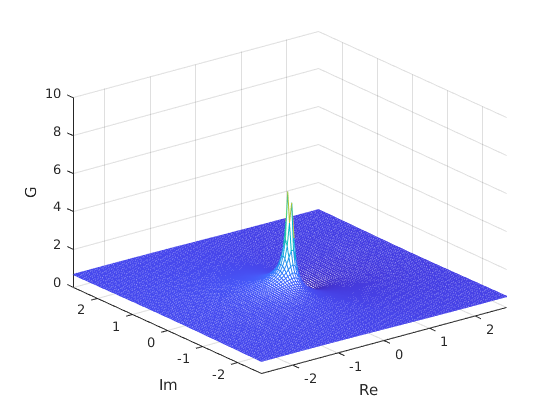

figure
meshc(R,I,G)
xlabel('Re')
ylabel('Im')
zlabel('G')
zlim([0 10])

Localización de los polos y los ceros

[Z,P,K]=tf2zpk([b0 b1],[1 -a1 -a2]);
P %polos

P = 0

Z %ceros

Z = 0.4032

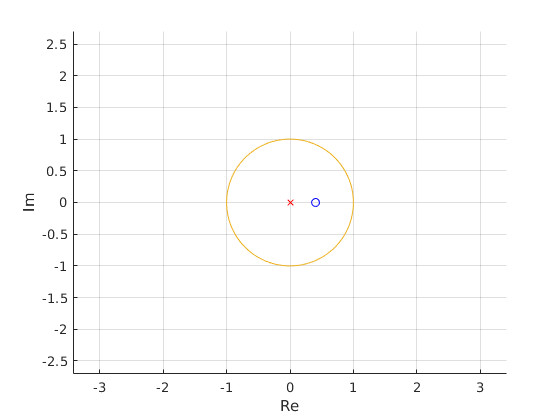

figure
hold on
xlim([-exten exten])
ylim([-exten exten])
for i=1:length(Z)
    plot(real(Z(i)),imag(Z(i)),'bo')
end
for i=1:length(P)
    plot(real(P(i)),imag(P(i)),'rx')
end
xlabel('Re')
ylabel('Im')
circulo(0,0,1)
grid on
axis equal
hold off

Compare las ubicaciones de polos y ceros con los picos y los valles de la gráfica 3D. Realice la simulación de la respuesta impulsional en el archivo excel y analice los resultados